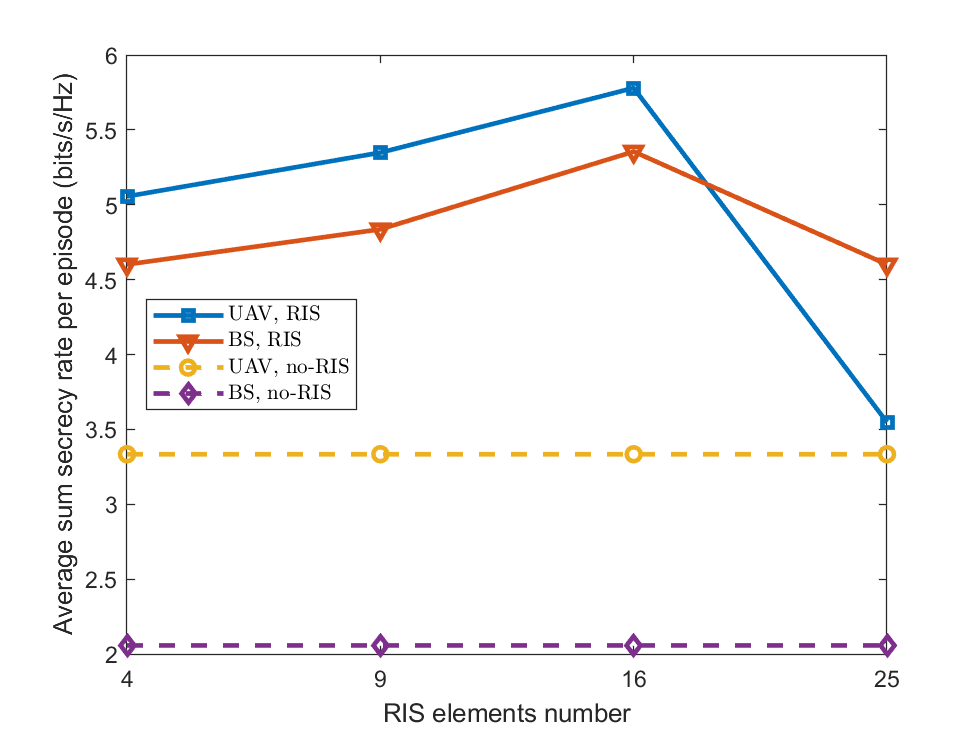

%load("rate.mat");
x = [1 2 3 4];
figure(5);
UAV_RIS = rate(1,:);
BS_RIS = rate(2,:);
UAV_no_RIS = rate(3,:);
BS_no_RIS = rate(4,:);

p = plot(x,UAV_RIS,'-s', ...
    x, BS_RIS,'-v', ...
    x, UAV_no_RIS,'--o', ...
    x, BS_no_RIS,'--d');
p(1).LineWidth = 2;
p(2).LineWidth = 2;
p(3).LineWidth = 2;
p(4).LineWidth = 2;
xlabel("RIS elements number");
ylabel("Average sum secrecy rate per episode (bits/s/Hz)");
xlim([1 4])
xticks(1:1:4);
xticklabels({'4','9','16','25'});
legend( ...
    'UAV, RIS',...
    'BS, RIS', ...
    'UAV, no-RIS', ...
    'BS, no-RIS',...
    'interpreter','latex',...
    'Location','west')